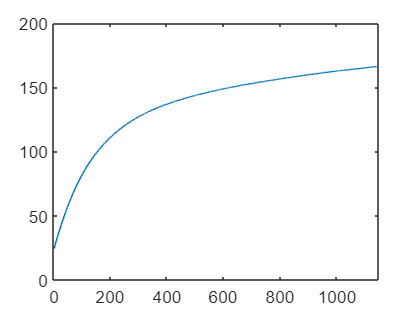

fileID = fopen('step_response/sensor5.txt', 'r');

formatSpec = '%d %f';

sizeA = [2 Inf];

A = fscanf(fileID,formatSpec,sizeA);

% xlabel('time [s]')
% ylabel('temperature [C]')
plot(A(1,:),A(2,:))



fclose(fileID);


x = [zeros(1,length(A)-1),ones(1,length(A))*17];

A2 = [ones(1,length(A)-1)*A(2,1),A(2,:)]

A2 =    24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000   24.6000



sys = tfest(A,3);

Error using tfest (line 113)
Invalid calling syntax for the
"tfest" command. Type "help tfest"
for more information.


plot(f,mag2db(abs(sys)))

step(sys)



